Decomposizione di Voronoi.

Prima troviamo un campionamento della mesh, ad esempio usando FPS.

M = load_ply('c:/users/rodola/workspace/data/faust/tr_reg_014.ply');

samples = fps_euclidean(M.VERT, 100, 1);

Visualizziamo i campioni

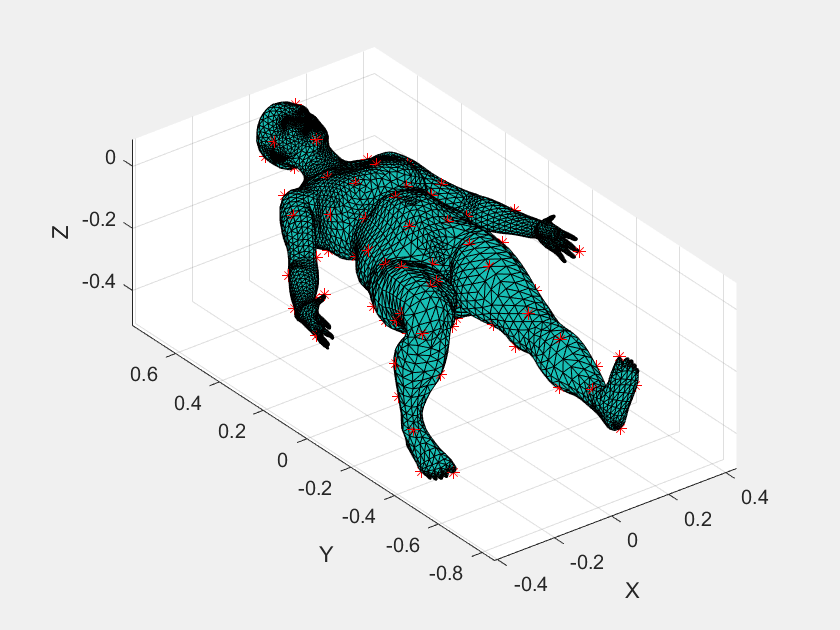

figure
plot_mesh(M)
hold on
plot_cloud(M,samples,'r*')

Calcoliamo le regioni di Voronoi

[~,voronoi] = min(pdist2(M.VERT, M.VERT(samples,:)),[],2);

figure, plot_scalar_map(M, voronoi)

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [13776×3 double]
     Vertices: [6890×3 double]

  Show all properties


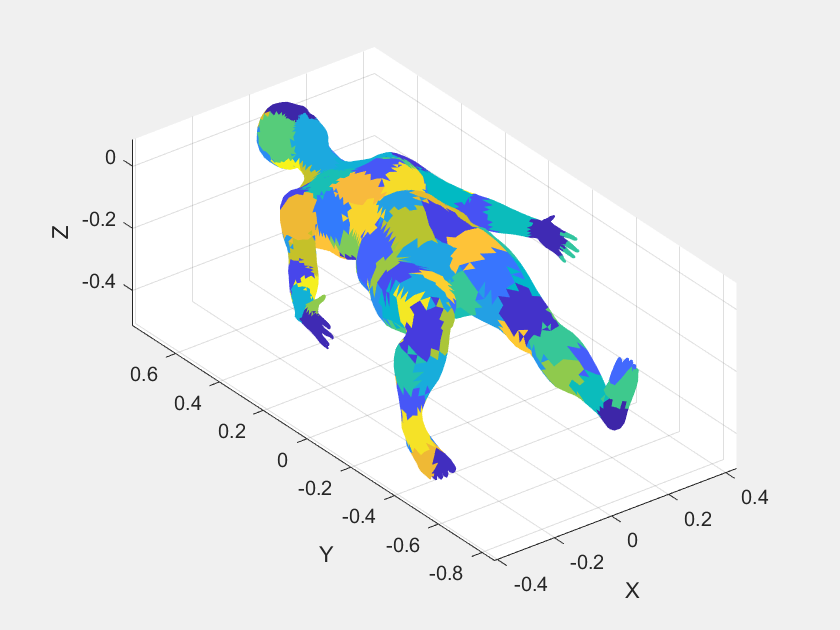

shading flat